# ***CDMA Transmission and Jamming Interference***

## ***Intro***

**perchè del progetto, cosa si analizzerà**

## **CDMA Transmission**

**cos'è, quando nate, come si implementano con immagini**

## **Esempio: trasmissione di un singolo segnale**

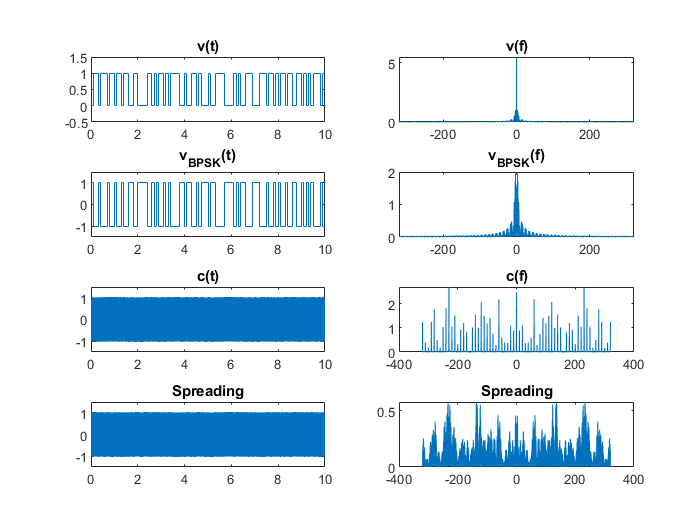

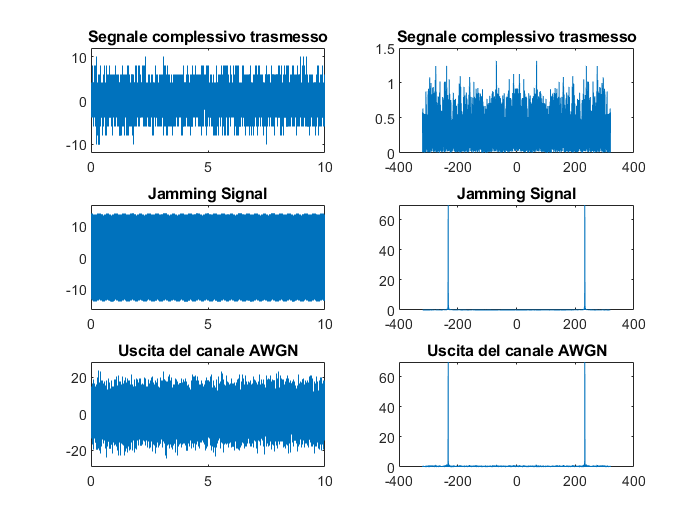

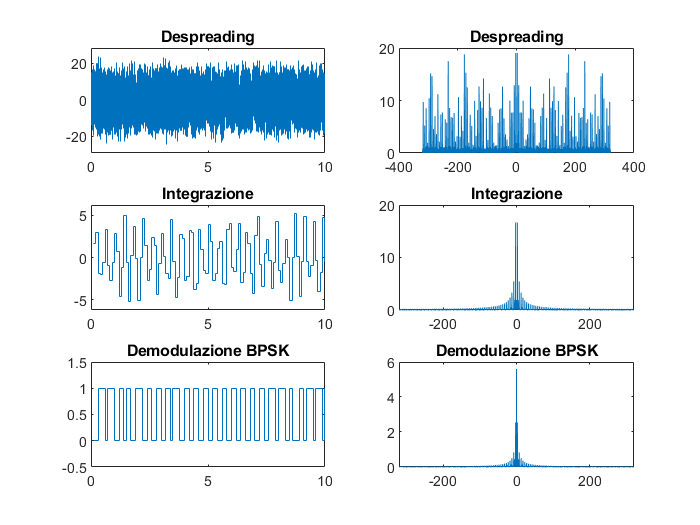

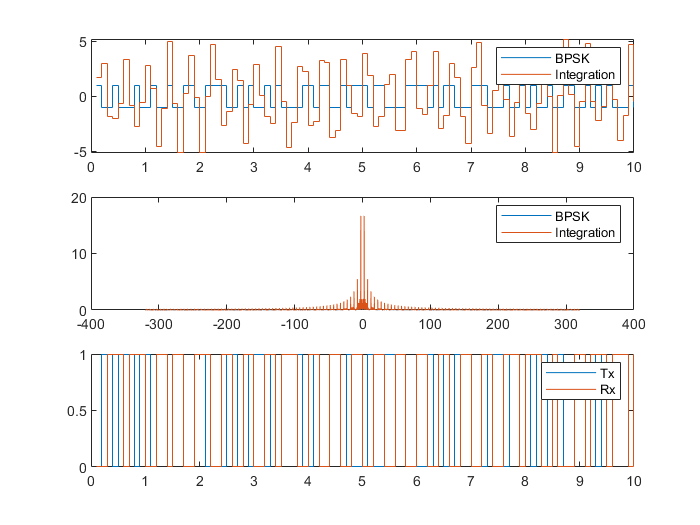

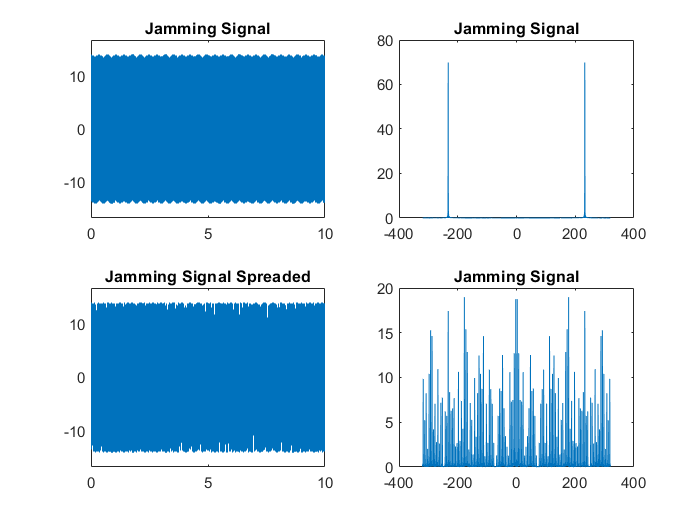

%% Variabili
Lc=64;                     %Processing gain
Tb=1/10;                   %Tempo di bit
len_signal=100;            %Lunghezza dei segnali trasmessi
Nuser=10;                %Numero di utenti
EbNo=20;   
plotting=true;           %Plotting nel dominio del tempo e frequenza
jammer_intensity=10;     %Rapporto potenza jammer/potenza segnale
jamming_type=1;            %Tipo Jammer 0:Broadband 1:SingleTone 2:MultiTone
alpha = 2.5;               %Valori da 1 a 5 -> Figura 10.44

%Matrici dei segnali in forma binaria
v_t_ref = sequence_generator(Nuser,len_signal);

[n_err,ber,rxbits] = cdma_transmission_and_metrics(v_t_ref,Lc,Tb,EbNo,plotting,jammer_intensity,jamming_type,alpha);

BER = mean(ber)

BER = 0.2260

### BER al variare di Lc e Nutenti (Senza Jamming)

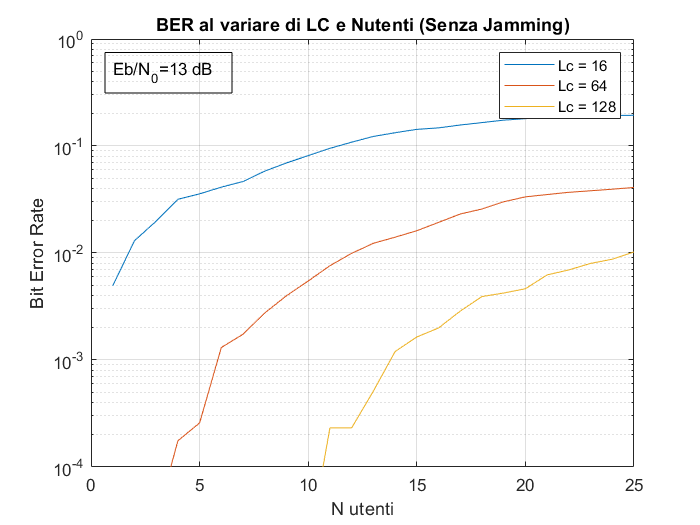

%% Variabili
Lc_values = [16 64 128];    %Processing gain
Tb=1/50;                    %Tempo di bit
len_signal=1000;            %Lunghezza dei segnali trasmessi
Nuser = 25;                 %Numero di utenti
EbNo = 20;   
mean_ber = zeros(length(Lc_values),Nuser);	%Nuser rappresenta il numero massimo di utenti da considerare
LegendsStrings = cell(length(Lc_values),1);

for i=1:length(Lc_values)
    for k = 1:Nuser
        v_t_ref = sequence_generator(k,len_signal);
        [n_err,ber,rxbits] = cdma_transmission_and_metrics(v_t_ref,Lc_values(i),Tb,EbNo,0,0,0,0);
        mean_ber(i,k) = mean(ber);
    end
    LegendsStrings{i} = ['Lc = ',num2str(Lc_values(i))];
end

mean_ber(mean_ber==0)=10^-9;  %Approssimazione ai fini di rappresentazione

figure
semilogy(1:Nuser, smoothdata(mean_ber(1,:)))
hold on
for k =2:length(Lc_values)
    semilogy(1:Nuser,smoothdata(mean_ber(k,:)))
end

grid
xlabel('N utenti')
ylabel('Bit Error Rate')
ylim([10^-4 1])
legend(LegendsStrings, 'Interpreter', 'none')
dim = [.15 .9 .0 .0];
str = join(['Eb/N_0=',num2str(round(db(EbNo,'power'))),' dB']);
annotation('textbox',dim,'String',str,'FitBoxToText','on');
title('BER al variare di LC e Nutenti (Senza Jamming)')

### BER al variare di EbN0 e Nutenti (Senza Jamming)

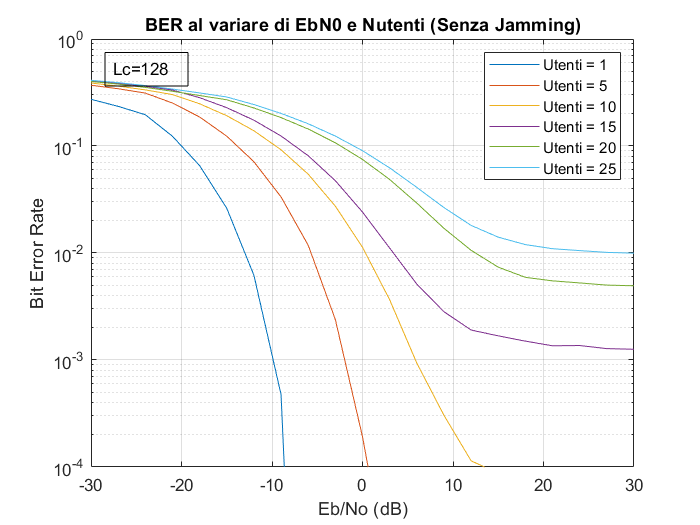

%% Variabili
Lc=128;                     %Processing gain
Tb=1/10;                    %Tempo di bit
len_signal=1000;             %Lunghezza dei segnali trasmessi
EbNos = logspace(-3,3,21);   
Nut = [1 5:5:25];           %Numero di utenti da considerare
mean_ber = zeros(length(Nut),length(EbNos));
LegendsStrings = cell(length(Nut),1);

for i=1:length(Nut)
    for k = 1:length(EbNos)
        v_t_ref = sequence_generator(Nut(i),len_signal);
        bers = zeros(1,10);
        for j=1:length(bers)
            [n_err,ber,rxbits] = cdma_transmission_and_metrics(v_t_ref,Lc,Tb,EbNos(k),0,0,0,0);
            bers(j) = mean(ber);
        end
        mean_ber(i,k) = mean(bers);
    end
    LegendsStrings{i} = ['Utenti = ',num2str(Nut(i))];
end

mean_ber(mean_ber==0)=10^-9; %Approssimazione ai fini di rappresentazione

figure
semilogy(db(EbNos, 'power'), smoothdata(mean_ber(1,:)))
hold on
for k =2:length(Nut)
    semilogy(db(EbNos, 'power'),smoothdata(mean_ber(k,:)))
end

grid
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')
ylim([10^-4 1])
legend(LegendsStrings, 'Interpreter', 'none')
dim = [.15 .9 .0 .0];
str = join(['Lc=',num2str(Lc)]);
annotation('textbox',dim,'String',str,'FitBoxToText','on');
title('BER al variare di EbN0 e Nutenti (Senza Jamming)')

### Fissiamo il numero di utenti e facciamo variare Lc e EbN0

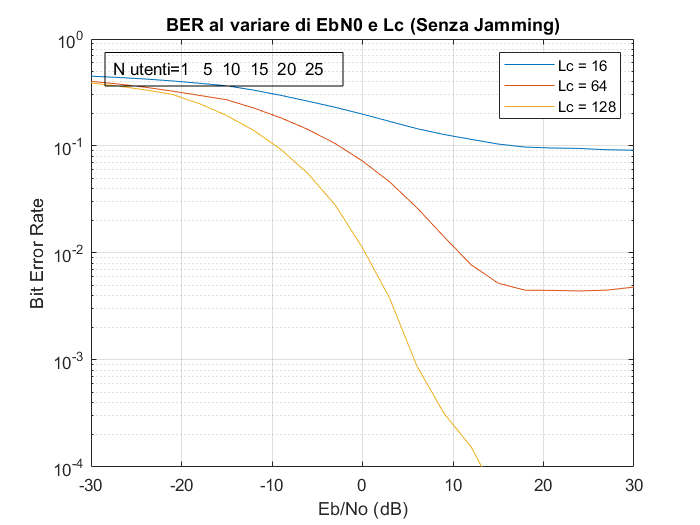

%% Variabili
Lc_values = [16 64 128];    %Processing gain
Tb=1/10;                    %Tempo di bit
len_signal=1000;            %Lunghezza dei segnali trasmessi
Nuser = 10;                 %Numero di utenti
EbNos = logspace(-3,3,21);	%Intervallo di canali da testare

mean_ber = zeros(length(Lc_values),length(EbNos));
LegendsStrings = cell(length(Lc_values),1);

for i=1:length(Lc_values)
    for k = 1:length(EbNos)
        v_t_ref = sequence_generator(Nuser,len_signal);
        bers = zeros(1,5);
        for j=1:length(bers)
            [n_err,ber,rxbits] = cdma_transmission_and_metrics(v_t_ref,Lc_values(i),Tb,EbNos(k),0,0,0,0);
            bers(j) = mean(ber);
        end
        mean_ber(i,k) = mean(bers);
    end
    LegendsStrings{i} = ['Lc = ',num2str(Lc_values(i))];
end

mean_ber(mean_ber==0)=10^-9; %Approssimazione ai fini di rappresentazione

figure
semilogy(db(EbNos, 'power'), smoothdata(mean_ber(1,:)))
hold on
for k =2:length(Lc_values)
    semilogy(db(EbNos, 'power'),smoothdata(mean_ber(k,:)))
end

grid
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')
ylim([10^-4 1])
legend(LegendsStrings, 'Interpreter', 'none')
dim = [.15 .9 .0 .0];
str = join(['N utenti=',num2str(Nut)]);
annotation('textbox',dim,'String',str,'FitBoxToText','on');
title('BER al variare di EbN0 e Lc (Senza Jamming)')

### BER al variare di Jamming intensity e type

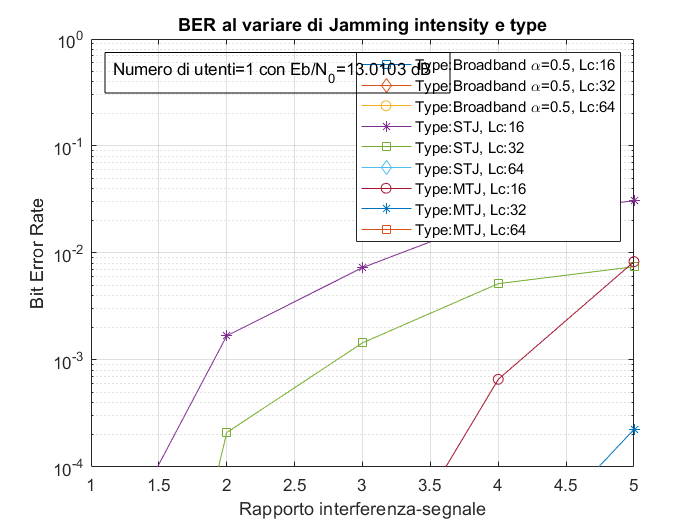

%% Variabili
Lcs=[16 32 64];    %Processing gain
Tb=1/10;           %Tempo di bit
len_signal=1000;   %Lunghezza dei segnali trasmessi
Nuser = 1;         %Numero di utenti
EbNo = 20;   
jam_intensity = [0:1:5];  %Rapporto potenza jammer/potenza segnale
jam_type = [0 1 2];       %Tipo Jammer 0:Broadband 1:SingleTone 2:MultiTone
alpha = 0.5;              %Valori da 1 a 5 -> Figura 10.44

%Matrici dei segnali in forma binaria
v_t_ref = sequence_generator(Nuser,len_signal);

jam_name = {'Broadband \alpha=0.5','STJ','MTJ'};
mean_ber = zeros(length(jam_type)*length(Lcs),length(jam_intensity));
LegendsStrings = cell(length(jam_type)*length(Lcs),1);

for i=1:length(jam_type)
    for z=1:length(Lcs)
        for k = 1:length(jam_intensity)
            bers = zeros(1,100);
            for j=1:length(bers)
                [n_err,ber,rxbits] = cdma_transmission_and_metrics(v_t_ref,Lcs(z),Tb,EbNo,0,jam_intensity(k),jam_type(i),alpha);
                bers(j) = mean(ber);
            end
            mean_ber((i-1)*length(Lcs)+z,k) = mean(bers);
        end
        LegendsStrings{(i-1)*length(Lcs)+z} = ['Type:',jam_name{i},', Lc:',num2str(Lcs(z))];
    end
end

mean_ber(mean_ber==0)=10^-9; %Approssimazione ai fini di rappresentazione

figure
semilogy(jam_intensity, smoothdata(mean_ber(1,:)),'-s')
hold on
for k =2:(length(jam_type)*length(Lcs))
    if mod(k,4)==0
        semilogy(jam_intensity,smoothdata(mean_ber(k,:)),'-*')
    elseif mod(k,4)==1
        semilogy(jam_intensity,smoothdata(mean_ber(k,:)),'-s')
    elseif mod(k,4)==2
        semilogy(jam_intensity,smoothdata(mean_ber(k,:)),'-d')
    else
        semilogy(jam_intensity,smoothdata(mean_ber(k,:)),'-o')
    end
end

grid
title('BER al variare della potenza del Jammer')
xlabel('Rapporto interferenza-segnale')
ylabel('Bit Error Rate')
ylim([10^-4 1])
legend(LegendsStrings, 'Interpreter', 'tex')
dim = [.15 .9 .0 .0];
str = join(['Numero di utenti=',num2str(Nuser),' con Eb/N_0=', num2str(db(EbNo, 'power')), ' dB']);
annotation('textbox',dim,'String',str,'FitBoxToText','on');
title('BER al variare di Jamming intensity e type')

### BER al variare di alpha

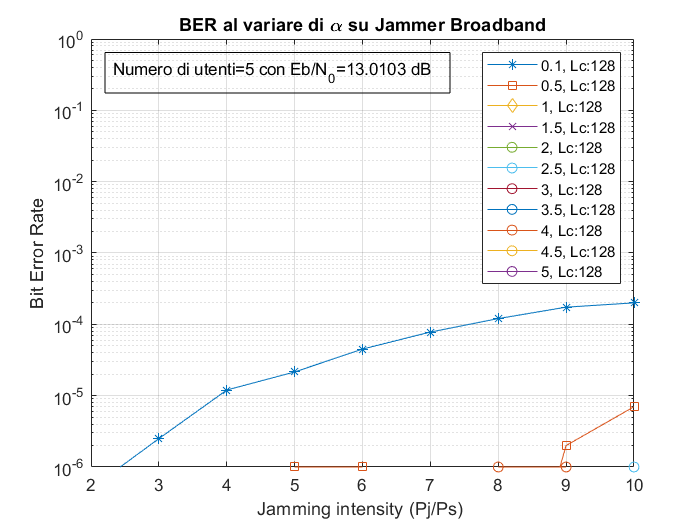

%% Variabili
Lcs=[128];                     %Processing gain considerati
Tb=1/10;                       %Tempo di bit
len_signal=1000;               %Lunghezza dei segnali trasmessi
Nuser = 5;                     %Numero di utenti
EbNo = 20;   
plotting = false;              %Plotting nel dominio del tempo e frequenza
jam_intensity = [0:1:10];      %Rapporto potenza jammer/potenza segnale
jam_type = 0;                  %Tipo Jammer 0:Broadband 1:SingleTone 2:MultiTone
alpha_test = [0.1 0.5:0.5:5];  %Valori da 1 a 5 -> Figura 10.44

v_t_ref = sequence_generator(Nuser,len_signal);

mean_ber = zeros(length(alpha_test)*length(Lcs),length(jam_intensity));
LegendsStrings = cell(length(alpha_test)*length(Lcs),1);

for i=1:length(alpha_test)
    for z=1:length(Lcs)
        for k = 1:length(jam_intensity)
            bers = zeros(1,100);
            for j=1:length(bers)
                [n_err,ber,rxbits] = cdma_transmission_and_metrics(v_t_ref,Lcs(z),Tb,EbNo,plotting,jam_intensity(k),jam_type,alpha_test(i));
                bers(j) = mean(ber);
            end
            mean_ber((i-1)*length(Lcs)+z,k) = mean(bers);
        end
        LegendsStrings{(i-1)*length(Lcs)+z} = [num2str(alpha_test(i)),', Lc:',num2str(Lcs(z))];
    end
end

mean_ber(mean_ber==0)=10^-9; %Approssimazione ai fini di rappresentazione

figure
semilogy(jam_intensity, smoothdata(mean_ber(1,:)),'-*')
hold on
for k =2:(length(alpha_test)*length(Lcs))
    if fix((k-1)/length(Lcs))==0
        semilogy(jam_intensity,smoothdata(mean_ber(k,:)),'-*')
    elseif fix((k-1)/length(Lcs))==1
        semilogy(jam_intensity,smoothdata(mean_ber(k,:)),'-s')
    elseif fix((k-1)/length(Lcs))==2
        semilogy(jam_intensity,smoothdata(mean_ber(k,:)),'-d')
    elseif fix((k-1)/length(Lcs))==3
        semilogy(jam_intensity,smoothdata(mean_ber(k,:)),'-x')
    else
        semilogy(jam_intensity,smoothdata(mean_ber(k,:)),'-o')
    end
end

grid
title('BER al variare di \alpha su Jammer Broadband')
xlabel('Jamming intensity (Pj/Ps) ')
ylabel('Bit Error Rate')
ylim([10^-6 1])
legend(LegendsStrings, 'Interpreter', 'tex')
dim = [.15 .9 .0 .0];
str = join(['Numero di utenti=',num2str(Nuser),' con Eb/N_0=', num2str(db(EbNo, 'power')), ' dB']);
annotation('textbox',dim,'String',str,'FitBoxToText','on');

### Trasferimento Audio

% %% Variabili
% Lc=64;                     %Processing gain
% Tb=1/10;                   %Tempo di bit
% EbNo = 20;   
% plotting = true;           %Plotting nel dominio del tempo e frequenza
% jammer_intensity = 5;      %Rapporto potenza jammer/potenza segnale
% jamming_type=0;            %Tipo Jammer 0:Broadband 1:SingleTone 2:MultiTone
% alpha = 2.5;               %Valori da 1 a 5 -> Figura 10.44
% 
% %% Trasferimento Audio
% audio_paths = {'audio/uomo_1.wav', 'audio/uomo_2.wav'};
% 
% [original_audio,v_t_ref,fr_vec] = create_tx_signal(audio_paths);
% [n_err,ber,rxbits] = cdma_transmission_and_metrics(v_t_ref,Lc,Tb,EbNo,plotting,jammer_intensity,jamming_type,alpha);
% [rec_sounds] = retrieve_tx_signals(rxbits, fr_vec, audio_paths);
% [sym_err_dem, sym_dem] = symerr(original_audio,rec_sounds,'row-wise');
% 
% ber
% sym_err_dem